clc; clear all; close all;

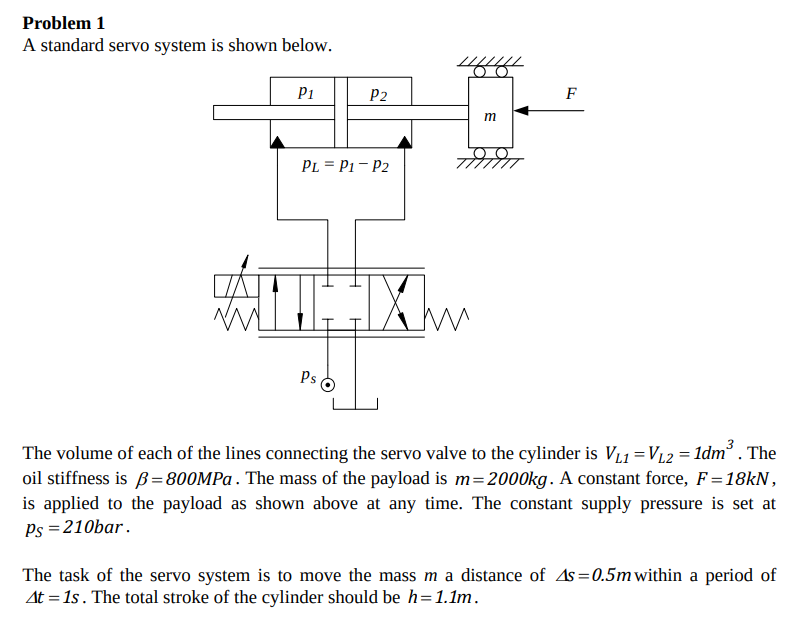

V_L1 = 10^-3; % m^3
V_L2 = V_L1; % m^3
beta = 800 * 10^6; % Pa
m = 2000; % kg
F = 18 * 10^3; % N
p_s = 210 * 10^5; % Pa
p_L = 2/3 * p_s; % p_L should be 2/3 of p_s

ds = 0.5; % m
dt = 1; % s
h = 1.1; % m

t_r = 0.1; % Ramp time, needed to calculate acceleration
dv = ds/(dt-t_r); % Average velocity
a = dv/t_r; % Acceleration, average velocity/ramp time
F_m = m * a % F = ma

F_m =           11111.1111111111


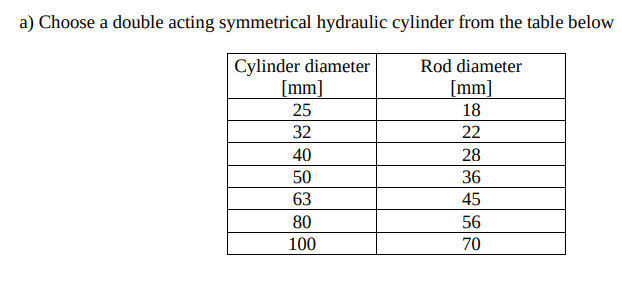

% a)
A = (F+F_m)/p_L % m^2 DONUT AREA!

A =        0.00207936507936508



cyls = [25 32 40 50 63 80 100]/1000; % Available cylinders
rods = [18 22 28 36 45 56 70]/1000;  % Available rods

A_cyls = pi./4 .* cyls.^2; % Areas of all cylinders
A_rods = pi./4 .* rods.^2; % Areas of all rods

A_donut = A_cyls - A_rods % Areas of all donut areas

A_donut =       0.000236404847182632      0.000424115008234622      0.000640884901332318      0.000945619388730528       0.00152681402964464       0.00256353960532927       0.00400553063332699



for i = 1:length(A_donut)
    if (A_donut(i) >= A) % if the donut area of area with index i is greater than or equal to the calculated area A, then the hydraulic cyl is valid
        A__donut_selected = A_donut(i) % Donut area of the selected cylinder
        cyls(i)*1000 % cylinder diameter of the selected hydraulic cyl
        rods(i)*1000 % rod diameter of the selected hydraulic cyl
        i % index
        break
    end
end

A__donut_selected =        0.00256353960532927


ans =     80


ans =     56


i =      6


disp("Selecting cylinder with 80mm diameter, and rod with 56 diameter.")

Selecting cylinder with 80mm diameter, and rod with 56 diameter.


% b)